## TOPIC 1: Introduction to MATLAB

ENGR105, 9/3/20

### Origins of MATLAB

MATLAB (Matrix Laboratory) is descended in part from the programming language FORTRAN, which was designed to support formula translation.

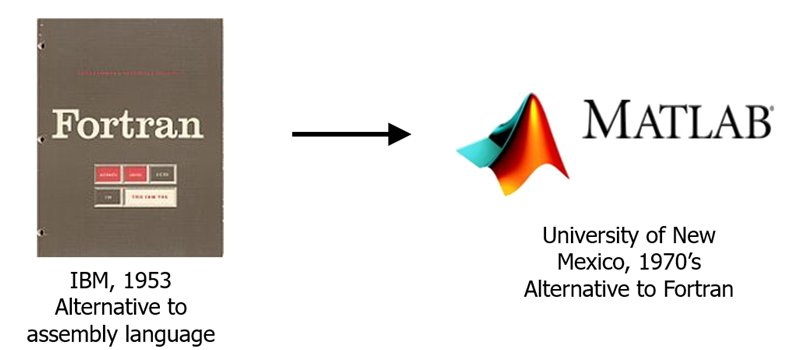

MATLAB is a high-level language that automatically interprets your instructions (code) into machine-level computation.Computation, ultimately performed at the transistor scale, is a physical process that takes  time. For this class, our focus is on computational solutions to problems. We want code that is:

- **Correct**: it robustly does what we want

- **Computationally efficient**: it does what we want quickly

- **Clear**: it is easy to understand and adapt what we are doing

### MATLAB Interface

The MATLAB interface is fully customizable, in that you can organize the following modules. The organization of these is a user preference.

- **Workspace: **this shows the variables stored and able to be called

- **Command Window:** depicts errors, notifications, and previously called lines of code. Also contains the command line (>>) in which bits of code can be tested. Scripts and functions may also be called using the command line.

- **Editor:** compose and view livescripts, scripts, and functions.

- **Command history:** lists previously called commands and functions.

- **Current Folder:** depicts the files and folders in the current directory.

- **Directory:** current directory (if you  contain a script or function if you are going to call it).

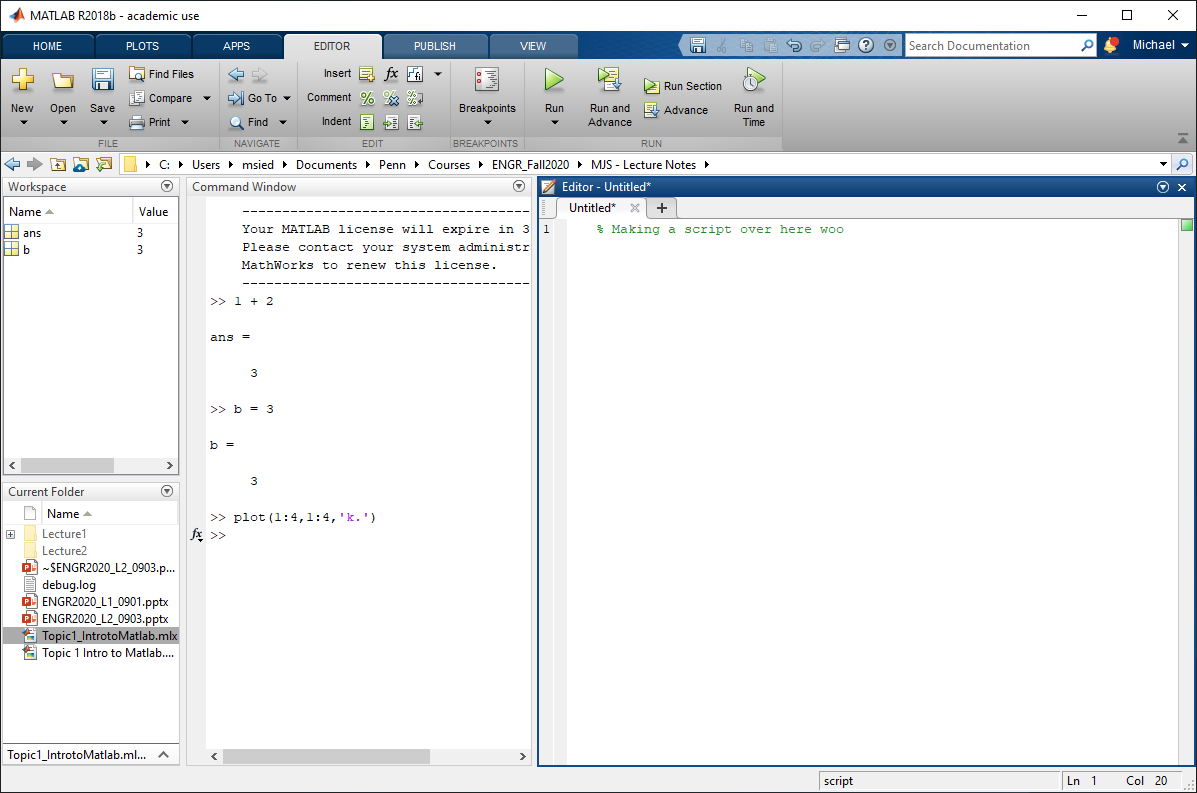

#### Working at the command line

The command line is useful for testing snippets of code or calling scripts or functions. Note that using a single "code block" in the LiveScript lecture notes *effectively* accomplishes the same thing. Note where the output is visible.

disp('hello world')

hello world


- Try inputting some values

- Note that when you enter something into the command line, the variable is stored in the workspace.

- `ans` contains the last output. **Avoid calling **`ans`, as it is very easy to lose track of what the last value called was. **Instead, use a statement  to define a variable such that the value of that variable can be called.**

#### Using LiveScripts

For lecture notes, we will use LiveScripts to organize material and interactively run through code.

- LiveScripts are organized into sections. To "run" the active section, press `cntl + Enter`

- To clear outputs from code, right-click and select "clear all outputs."

            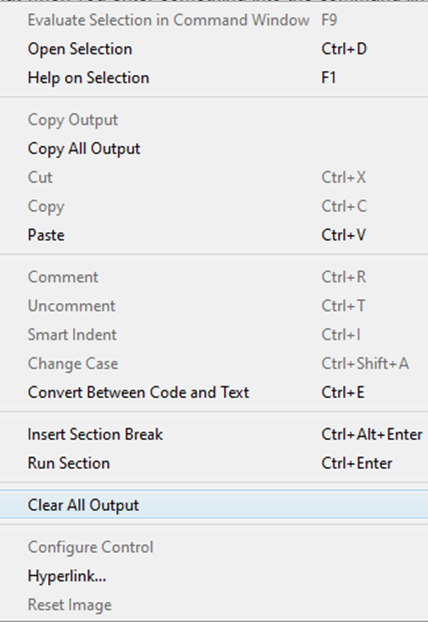

### General notes on MATLAB syntax and peculiarites 

#### Statements and Expressions

Expressions and statements are the fundamental building blocks of code. Expressions are located on the right side of a statement.

        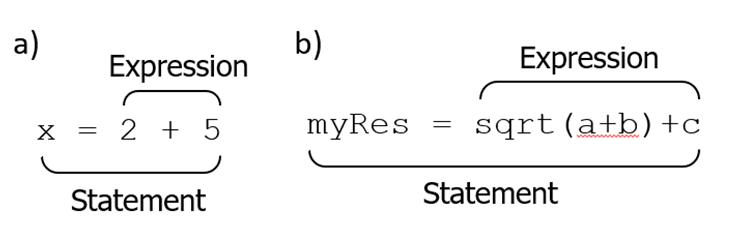

The above reads as:

- a) "2 and 5 are added and stored in variable x"

- b) "the square root of the sum of variables `a` and `b` is added to `c` and stored in varilable `myRes`"

These statements would execute:

These statements would not execute:

#### Naming conventions for variables 

In the above examples, a **scalar** is stored in a **variable **that becomes visible in the **Workspace**. When creating variables, the following naming conventions should be followed:

- Must consist of only the letters a-z, the digits 0-9, and underscores (_)

- Must start with a letter

- Should not overwrite built-in functions

- Should not overwrite built-in variables

#### Comments, suppression, and separation

Comments are initiated by percent signs (`%`). Comments are vary important for helping **you** and others understand your code.

%This is a comment, they are useful

Some resources quote "one comment for every three lines of code" - this is dependent on the code. Some code contains more characters than productive syntax. When in doubt, add comments for clarity. When using MATLAB in Windows, large swaths of highlighted code can be *commented* using "`ctrl`" + "`r`" and *uncommented* using "`ctrl`" + "`t`".

A semicolon (`;`) placed at the end of a statement suppresses output to the command line 

x = 2+5; %This comment is suppresed 
y = 2+3 %This comment is not suppresed

y = 5

**It is  good practice when starting to have one statement per line**, for ease of visualization. However, commas can be used to combine statements on a single line without suppression

x = 2 + 5, y = x+3

x = 7

y = 10

#### Procedural programming order

We will primarily use MATLAB as a procedural programming interface. Lines of contiguous code are executed in the order written and the results of expressions are placed into the statement variable.

% First, the scalar 3 is placed in variable x
x = 3;
% Second, variable x (equal to 3) is squared, 2 is added, and the result 
% is placed back into variable x (now equal to 11)
x = x^2 + 2;
% Third, variable x (equal to 11) and 5 are added and placed in variable y
y = x + 5

y = 16

#### Errors and Warnings

An extremely useful feature of MATLAB is that it alerts you (and stops running) when your code has an **error**. For example, typing `sin` into the command line and running the code produces the following error.

                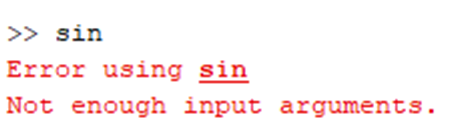

The nature of the error text provides insight into what went wrong. In this case, `sin` is the built-in sine function in MATLAB and the error occurs because we are not providing enough input arguments to that function. 

**Warnings**, on the other hand, do not interrupt the code but alert that user of a potential oversight or computational inefficiency. Errors and warnings correspond to red and yellow lines in the right bar of a MATLAB script file, as well as annotations in the text. In this LiveScript file, the following warning is observed by hovering the cursor over the warning alert.

                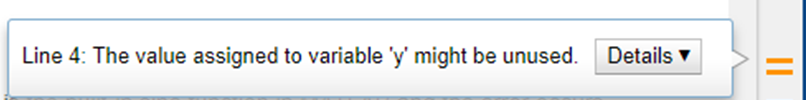

#### Using the Editor

Assemblages of code can be composed in the editor window and stored as an .m file for more permanence. These assemblages of code are referred to as either functions or scripts.Functions start with the `function` declaration whereas scripts are just assemblages of statements.

            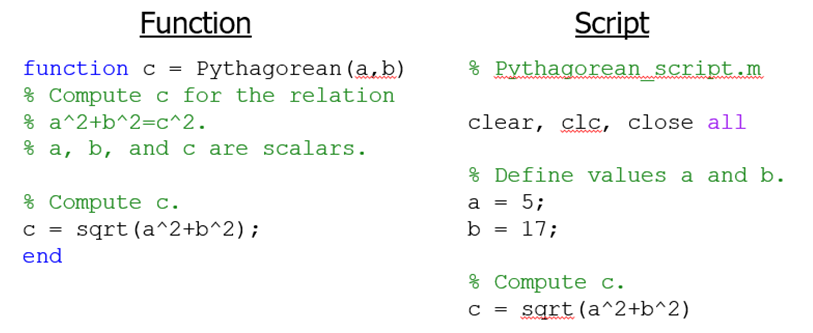

#### Functions

Functions usually take inputs and return outputs. In the above function:

- The function is called by the name `Pythagorean`

- Inputs `a` and `b `are provided as scalar numbers

- The value of `c` is returned

**NOTE: when incorporating functions into LiveScripts, all functions are stored at the end of the LiveScript document.**

Functions can be invoked (i.e. "called") from the command line or another function.

Pythagorean(1,1)

ans = 1.4142

result = Pythagorean(1,1)

result = 1.4142

**Note: when you assign variables in a LiveScript, the variable is stored in the Workspace.**

- Variables created within a function stay within the function - only function outputs are returned

- For example, the command line call `result = ``Pythagorean(2,5)` yields the variable `result` in the user workspace, but the variables in the function (`a`, `b`, and `c) `are nowhere to be found

#### Scripts

Scripts and command line calls operate in the user workspace and the variables generated can be seen by the command line and other scripts (but not functions). Scripts are saved as` .m` files.

- New scripts or functions can be created by clicking the "New" button in the MATLAB interface.

- To open a script or function, either a) navigate to a .m file in the directory and click to open it, or b) type `open <name of function>` into the command line.

NOTE: you can open some preexisting functions in MATLAB. **DO NOT MODIFY THESE.**

#### Clearing the workspace and figures

It is useful to purge the workspace memory at the beginning of a script using the `clear `command to avoid accidental use of old variables. 

- `clear`: clears the Workspace. Can also be used to clear specific variables

- `clc`: purges the command line

- `close all:` closes all figure windows

% Example code demonstrating the clear command. a is cleared from the
% workspace below
a = 5;
b = 3;
clear a

#### Working directory and paths

MATLAB can see the contents (e.g. files, scripts, and functions) in a set of pre-installed folders (i.e. paths) and your current working folder. You can see a list of all paths MATLAB can see by inputting `path `at the command line. When invoking an `.m` file from a path that MATLAB can't see, it will query you if you would like to "Change Folder" or "Add to Path" - **usually "Change Folder" is the best selection**. 

**To avoid unnecessary headaches, you are encouraged to create a new folder for each homework assignment or project.**

#### Interrupting code execution

Runaway code (code that does not terminate naturally) can be interrupted:

- `ctrl + c` (Windows)

- `command + period` (Mac)

- The "Pause" and "Stop" buttons in the editor can also be used.

% Example of infinite loop. Try interrupting the code. Be careful with
% infinite loops!
a = 1;
while a ~= 1 
    
end

#### MATLAB documentation and help

MATLAB has extensive help documentation. Some routes to the help documentation include:

- Enter` help <term>` on the command line (*the first thing I often try*)

- Help symbol, F1, or the help search bar in MATLAB

- The “Google method” -> google "MATLAB" and then what you are looking for.

**One goal of this course is that these notes will be a useful "help" resource for you in your future classes.**

You can also open the reference documentation for a function from a link in the command line.

help sin

 sin    Sine of argument in radians.
    sin(X) is the sine of the elements of X.
 
    See also asin, sind, sinpi.

    Documentation for sin
    Other functions named sin



The following is the reference documentation for the `sin` function.

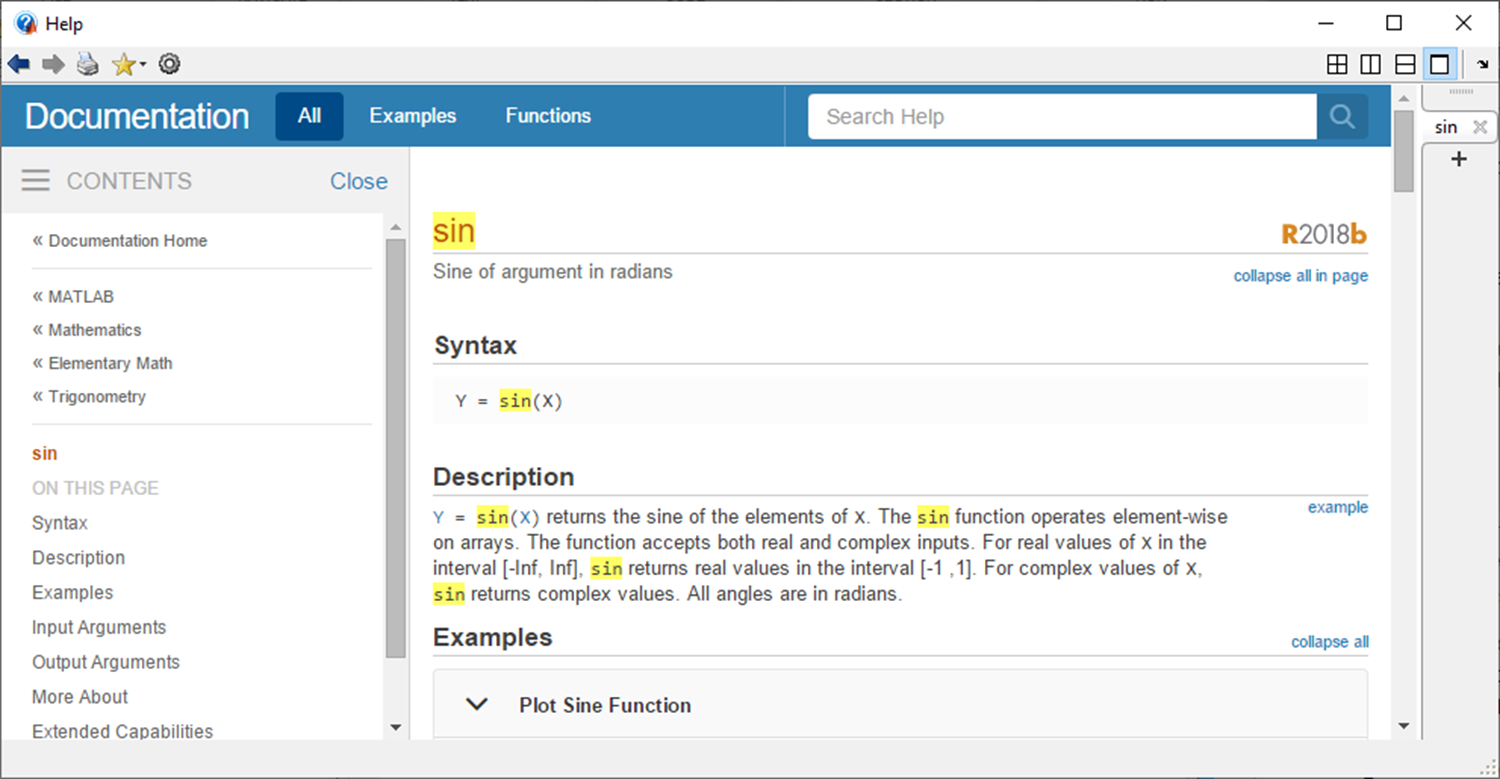

Note that the related functions (“See Also” section) at the end of each help page are useful for discovering functionality.

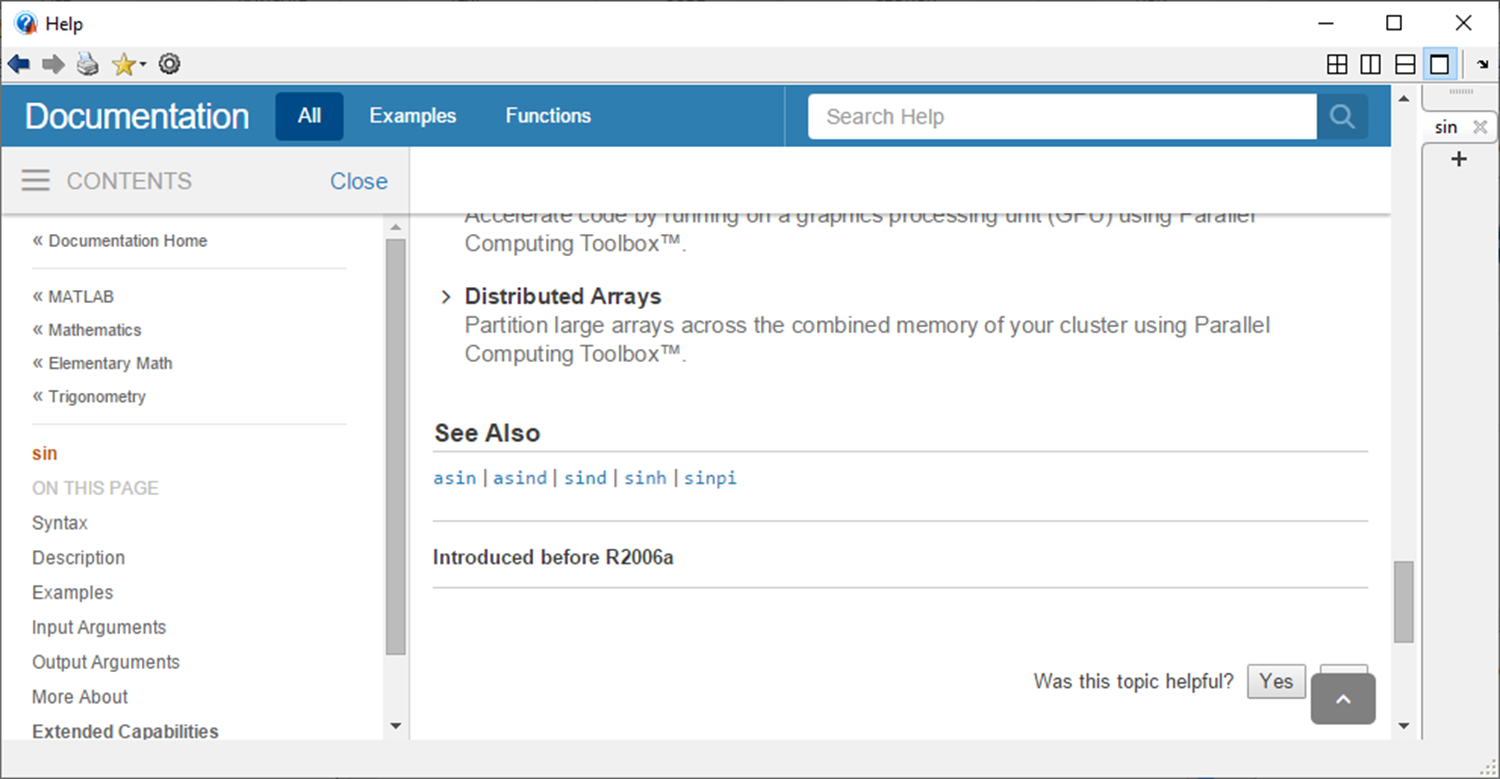

#### Built-in MATLAB functions

MATLAB has thousands of built-in functions for evaluating common mathematical and statistical functions. You will use these and **many** other functions both in this class and during the rest of your time at Penn. When in doubt, just check the help documentation.

a = sin(2*pi)

a = -2.4493e-16

b = sum([3, 4, 5])

b = 12

### Basics of vectors: 1- D arrays

MATLAB is well-suited to work with arrays, which you can think of as sequences of numbers, where the **value** and **index** of each entry define the array. A 1-D array is known as a **vector** in MATLAB.

% Explicityly define an array with 5 numbers

x = [1, 3, 9, 11, -10.2];

An explicit description of a vector is useful when the vector components are irregular. 

#### Creating vectors with slice notation

An often quicker way to produce vectors is to use the colon (`:`) operator. This enables you to create a vector by defining the **lower bound, upper bound, and increment size.**

% Create an array with numbers 1 though 15
x = 1:15;
% Create an array starting at 4 and increasing by 2 to 28
y = 4:2:28;
% Create an array starting at -1.3 and increasing by 0.1 to the value 1.3
z = -1.3:0.1:1.3;

Note: MATLAB will not include values above the upper bound specified in the slice notation. Note the values in the following array.

a = 1:2:6;

#### Creating vectors with `linspace()` and `logspace()`

Another way to create vectors is to use `linspace()` and `logspace()` when the **number of increments** is more important than the increment size. 

- `linspace` creates a vector of uniformly spaced components in linear space

% Create a vector with 5 elements uniformly spaced between (and including) 1 and 5
a = linspace(1,5,5)

a =      1     2     3     4     5


- `logspace` creates a vector of uniformly spaced components in (base-10) logarithmic space

% Create a vector with 5 elements uniformly spaced logarithmically between 
% (and including) 10^1 and 10^5
b = logspace(1,5,5) 

b =           10         100        1000       10000      100000


#### Other vectors 

In addtion to the above, many other types of vectors can be created. Here are a few more, useful examples. 

- **Empty** vector

c = []


c =

     []



- **Ones** vector

d = ones(1,5)

d =      1     1     1     1     1


- **Zeros** vector

f = zeros(1,5)

f =      0     0     0     0     0


#### Accessing vector indices

Individual vector indices or groups of vector indices may be accessed/extracted. For the following assume we have defined the following vector in memory:

x = [5, 9, 4, 1, 7, 3, 4, 8];

- Access the first vector index:

y = x(1)

y = 5

- Access a range of vector indices:

x(1:3)

ans =      5     9     4


x(6:8)

ans =      3     4     8


- Access the last vector index

x(end)

ans = 8

- Access the second-to-last vector index

x(end-1)

ans = 4

- Access discrete indices in any order

x([3, 6, 1])

ans =      4     3     5


#### Replacing indices and adding indices to vectors

The existing contents of a vector may be replaced and indices may be added. Assume we have defined the following vector in memory, which we will continuously modify:

x = [1, 2, 3]

x =      1     2     3


- Replace the first index

x(1) = 5

x =      5     2     3


- Replace the first and second indices

x(1:2) = [8,9]

x =      8     9     3


- Replace the first and third indices

y = [8, 9, 3]

y =      8     9     3


y([1,3]) = [5,1]

y =      5     9     1


- Replace the ultimate and penultimate indices

y(end-1:end) = [6,8]

y =      5     6     8


- Add a scalar after the last index 

z = [2, 6, 8]

z =      2     6     8


z(end+1) = 4

z =      2     6     8     4


- Add multiple numbers to the end of the vector

z(end+1:end+2) = [5,7]

z =      2     6     8     4     5     7


- Replace all odd indices with a scalar

z(1:2:end) = 1

z =      1     6     1     4     1     7


- Replace all even indices with a scalar 

z(2:2:end) = 4

z =      1     4     1     4     1     4


- Add an index more than one index after the ultimate index

z(end+2) = 7

z =      1     4     1     4     1     4     0     7


The rules for replacing vector indices are thus:

- Scalars can replace a single index or multiple indices

- Vectors can replace multiple indices of a vector if the length of the replacement equals the number of indices

x = [5, 2, 1, 8]

x =      5     2     1     8


#### Removing vector indices

Vector indices may be removed by specifying an empty set (empty vector). 

x = [5, 3, 9, 4, 1, 6]

x =      5     3     9     4     1     6


- Remove the first index

x(1) = []

x =      3     9     4     1     6


- Remove odd indices

x(1:2:end) = []

x =      9     1


#### Concatenating vectors

Multiple vectors may be combined via concatenation, provided both vectors are oriented correctly (both row vectors).

x = [9, 5, 8, 2]

x =      9     5     8     2


- Concatenate same vector

x(1) = []

x =      5     8     2


- Concatenate multiple vectors

x(1:2:end) = []

x = 8

#### Operations on vectors

You can perform mathematical operations on arrays just as you can scalar values (in most cases).

- You can **add** and **subtract** two arrays in MATLAB as long as they are the same size - if they are not the same size you will get an error.

x = [1 2 3 4 5];
y = [7 8 9 10 11];

% element-wise addition adds corresponding elements
z = x + y;

- Multiplication and division are different -- simply using * and / will perform matrix multiplication and division (which we will explore later)

- Instead, **use a period (**`.`**) to perform element-wise multiplication and division **

z1 = x.*y; % element-wise multiplication
z2 = x./y; % element-wise division

Almost all of MATLAB’s built-in functions will accept arrays as arguments and perform operations on these arrays in an element-wise manner.

x = 1:10:1000;
% Compute the square root of each element in the array x
y = sqrt(x);

We will see later that **vectorization** in this way is more computationally efficient than using loops to operate on each element. In addition, operations can be performed on the output from each function.

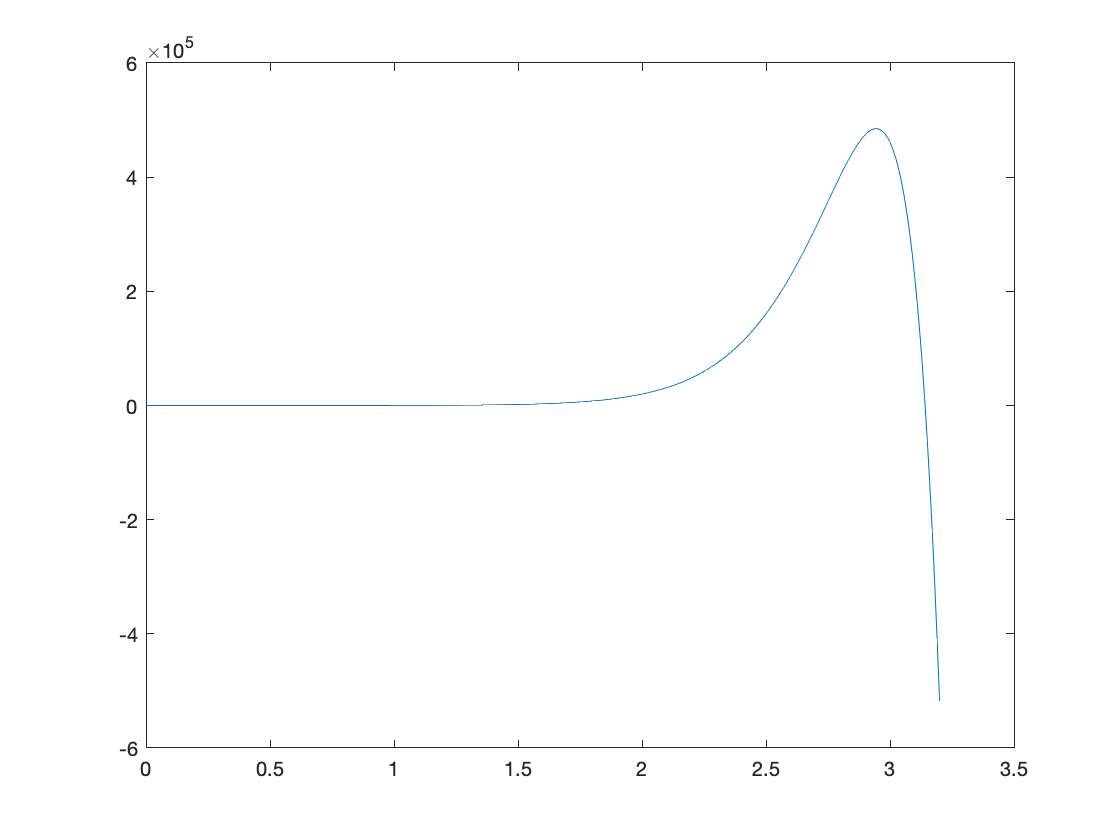

% create an array of values
x = 0:0.01:3.2;  

% evaluate an expression on every element in % the array x producing a new array called y
y = exp(5*x).*sin(x);

% produce a plot 
plot(x, y) 

## All functions contained in this note sheet

function c = Pythagorean(a,b)
    % Compute c for the relation
    % a^2+b^2=c^2.
    % a, b, and c are scalars.
     
    % Compute c.
    c = sqrt(a^2+b^2);
end